## Q2 - part d | ARMAX

clc; clear;

%%

load HW5_question2


u3 = Z3.u;
y3 = Z3.y;

u3_val = u3;%(601:end);
y3_val = y3;%(601:end);

u3 = u3(1:600);
y3 = y3(1:600);


%%

% System Z3 **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> System III Identification Begins:------------------------------\n")

>>> System III Identification Begins:------------------------------


%%

Ts = 0.5; 
t = 0:Ts:length(u3)*Ts-Ts;
t_val = 0:Ts:length(u3_val)*Ts-Ts;
N = length(y3);
N_val = length(y3_val);

data3 = iddata(y3,u3,Ts);



%%

fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nc = degree;
    nk = 1;
    p = na+nb+nc;
    
    try
        sys = armax(data3, [na nb nc nk]);
        armax_y_hat_3 = lsim(sys, u3, t);
    catch
        break
    end

    [r2_armax, mse_armax] = rSQR(y3, armax_y_hat_3);

    error = y3 - armax_y_hat_3;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_armax, mse_armax, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_armax];
    MSEs = [MSEs; mse_armax];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=-0.018452 | MSE=142.112996 | var=142.827132 | s_hat=85267.797605 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.618455 | MSE=53.240136 | var=53.777915 | s_hat=31944.081791 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.997544 | MSE=0.342692 | var=0.347911 | s_hat=205.615249 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.997525 | MSE=0.345340 | var=0.352388 | s_hat=207.204135 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.997550 | MSE=0.341931 | var=0.350699 | s_hat=205.158819 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.997525 | MSE=0.345310 | var=0.355989 | s_hat=207.185720 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.997562 | MSE=0.340202 | var=0.352541 | s_hat=204.121001 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.997547 | MSE=0.342297 | var=0.356559 | s_hat=205.377944 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.997559 | MSE=0.340617 | var=0.356667 | s_hat=204.370013 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=-125826009174572493536768118134755543170640556739539718462485297386516870056911155938693256083981303081395638203469706268001320304640.000000 | MSE=17557543286192878303977126696753971652407381690920112331606633980560099215254815793885422099465405215025172511575615599875553945976832.000000 | var=18481624511781976498468450057307688690466042198549780474032427003276792134823285606267235532115826770944118350965226681020532737966080.000000 | s_hat=10534525971715726356997633668879208934151504545072629084738358687508490015477576564143157302475516304647869509411988309042532905436315648.000000 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=0.997579 | MSE=0.337828 | var=0.357489 | s_hat=202.696513 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.997573 | MSE=0.338651 | var=0.360267 | s_hat=203.190541 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.997609 | MSE=0.333672 | var=0.356869 | s_hat=200.203345 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.997562 | MSE=0.340247 | var=0.365857 | s_hat=204.148079 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.997587 | MSE=0.336699 | var=0.363998 | s_hat=202.019156 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.997573 | MSE=0.338704 | var=0.368157 | s_hat=203.222405 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.997380 | MSE=0.365555 | var=0.399513 | s_hat=219.332787 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.997587 | MSE=0.336664 | var=0.369960 | s_hat=201.998141 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=-1648593344102371115963756052480.000000 | MSE=230041858517882968689305202982912.000000 | var=254189898914787847332373989425152.000000 | s_hat=138025115110729804560243590078398464.000000 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.997657 | MSE=0.326885 | var=0.363205 | s_hat=196.130925 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.997632 | MSE=0.330448 | var=0.369215 | s_hat=198.268632 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=0.997591 | MSE=0.336155 | var=0.377702 | s_hat=201.692817 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.997681 | MSE=0.323529 | var=0.365569 | s_hat=194.117158 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.997635 | MSE=0.330062 | var=0.375070 | s_hat=198.037106 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.997566 | MSE=0.339607 | var=0.388122 | s_hat=203.764018 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.997559 | MSE=0.340676 | var=0.391581 | s_hat=204.405480 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.997616 | MSE=0.332600 | var=0.384509 | s_hat=199.559918 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.997619 | MSE=0.332271 | var=0.386361 | s_hat=199.362358 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.997649 | MSE=0.328021 | var=0.383650 | s_hat=196.812558 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.997669 | MSE=0.325252 | var=0.382650 | s_hat=195.151366 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.997638 | MSE=0.329624 | var=0.390088 | s_hat=197.774532 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.997675 | MSE=0.324456 | var=0.386258 | s_hat=194.673836 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.997702 | MSE=0.320615 | var=0.383970 | s_hat=192.369125 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.997581 | MSE=0.337493 | var=0.406618 | s_hat=202.495879 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=-1.550069 | MSE=355.832210 | var=431.311770 | s_hat=213499.325965 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.997551 | MSE=0.341680 | var=0.416683 | s_hat=205.008258 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.997603 | MSE=0.334407 | var=0.410316 | s_hat=200.644403 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.997849 | MSE=0.300121 | var=0.370519 | s_hat=180.072353 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.997732 | MSE=0.316442 | var=0.393096 | s_hat=189.865234 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.997716 | MSE=0.318701 | var=0.398376 | s_hat=191.220378 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.997692 | MSE=0.322026 | var=0.405064 | s_hat=193.215528 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.997999 | MSE=0.279161 | var=0.353368 | s_hat=167.496322 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.997757 | MSE=0.313006 | var=0.398733 | s_hat=187.803468 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.997663 | MSE=0.326079 | var=0.418050 | s_hat=195.647216 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.997479 | MSE=0.351783 | var=0.453914 | s_hat=211.069819 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.997682 | MSE=0.323393 | var=0.419991 | s_hat=194.036053 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.997703 | MSE=0.320487 | var=0.418937 | s_hat=192.292055 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.997697 | MSE=0.321325 | var=0.422796 | s_hat=192.795169 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.997728 | MSE=0.317034 | var=0.419912 | s_hat=190.220108 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.997869 | MSE=0.297308 | var=0.396411 | s_hat=178.384992 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.997976 | MSE=0.282473 | var=0.379158 | s_hat=169.483588 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.997886 | MSE=0.294981 | var=0.398623 | s_hat=176.988718 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.998073 | MSE=0.268944 | var=0.365910 | s_hat=161.366418 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=-3686277843097798426281504879411200.000000 | MSE=514376822563984101568946978601041920.000000 | var=704625784334224869445986179293904896.000000 | s_hat=308626093538390468024917911465092972544.000000 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.996363 | MSE=0.507536 | var=0.700050 | s_hat=304.521774 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=-580458794.734296 | MSE=80996214525.222488 | var=112494742396.142349 | s_hat=48597728715133.492188 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=-5627083987239348441338474440082616847936331658092020488813218118352948033751042957878300338973786512352092176535973744811092690658581765160960.000000 | MSE=785193548846681373598818242748894109636261970346387969001817639447049896934495660703666041904424564257908916203857528527645494902485319786954752.000000 | var=1098172795589764370949919076896442996966136595344444756198559718967858533664472343448627709824581572386726223809777210809408873222717698159411200.000000 | s_hat=471116129308008917043725698696634261658632351001136846521732608758085206371763347012013436631113110393887954210990383379192864148510848142807138304.000000 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.997909 | MSE=0.291763 | var=0.410934 | s_hat=175.058053 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=-283758802.210482 | MSE=39595211696.606354 | var=56163420846.250130 | s_hat=23757127017963.804688 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=-29.955011 | MSE=4319.408661 | var=6170.583801 | s_hat=2591645.196465 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=0.998127 | MSE=0.261402 | var=0.376118 | s_hat=156.841228 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=0.997952 | MSE=0.285832 | var=0.414249 | s_hat=171.498993 | 


-------------------------------------------------------------


>>> Degree = 63 : R2=0.997982 | MSE=0.281581 | var=0.411067 | s_hat=168.948393 | 


-------------------------------------------------------------


>>> Degree = 64 : R2=0.997964 | MSE=0.284077 | var=0.417761 | s_hat=170.446293 | 


-------------------------------------------------------------


>>> Degree = 65 : R2=0.998124 | MSE=0.261766 | var=0.387801 | s_hat=157.059576 | 


-------------------------------------------------------------


>>> Degree = 66 : R2=0.998143 | MSE=0.259171 | var=0.386822 | s_hat=155.502580 | 


-------------------------------------------------------------


>>> Degree = 67 : R2=0.998289 | MSE=0.238795 | var=0.359090 | s_hat=143.276737 | 


-------------------------------------------------------------


>>> Degree = 68 : R2=0.997888 | MSE=0.294761 | var=0.446607 | s_hat=176.856450 | 


-------------------------------------------------------------


>>> Degree = 69 : R2=0.997994 | MSE=0.279905 | var=0.427336 | s_hat=167.943087 | 


-------------------------------------------------------------


>>> Degree = 70 : R2=0.998023 | MSE=0.275797 | var=0.424304 | s_hat=165.478490 | 


-------------------------------------------------------------


>>> Degree = 71 : R2=-97565175149816270282569082208256.000000 | MSE=13614075477362121066502125218955264.000000 | var=21107093763352129116451804750544896.000000 | s_hat=8168445286417273912726616217332219904.000000 | 


-------------------------------------------------------------


>>> Degree = 72 : R2=-131601823498516.015625 | MSE=18363490408500260.000000 | var=28692953763281652.000000 | s_hat=11018094245100154880.000000 | 


-------------------------------------------------------------


>>> Degree = 73 : R2=0.994995 | MSE=0.698335 | var=1.099740 | s_hat=419.001073 | 


-------------------------------------------------------------


>>> Degree = 74 : R2=0.998163 | MSE=0.256295 | var=0.406817 | s_hat=153.776940 | 


-------------------------------------------------------------



fprintf("=================================================================\n")

%%


fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 67 


na = bestFitDegree;
nb = bestFitDegree;
nc = bestFitDegree;
p = na+nb+nc;

BestFitModel_3 = armax(data3, [na nb nc 1])

BestFitModel_3 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                                                
                                                                                                         
  A(z) = 1 - 0.2286 z^-1 + 0.1664 z^-2 + 0.4388 z^-3 - 0.263 z^-4 + 0.275 z^-5 + 0.1243 z^-6             
          - 0.1869 z^-7 + 0.4421 z^-8 - 0.04054 z^-9 - 0.1755 z^-10 - 0.08172 z^-11 - 0.103 z^-12        
          - 0.04915 z^-13 + 0.2309 z^-14 + 0.04809 z^-15 + 0.1812 z^-16 + 0.1346 z^-17 - 0.1456 z^-18    
          + 0.1887 z^-19 + 0.1068 z^-20 - 0.2874 z^-21 + 0.2651 z^-22 - 0.0965 z^-23 + 0.01195 z^-24     
          + 0.2021 z^-25 - 0.1148 z^-26 - 0.06295 z^-27 + 0.2156 z^-28 - 0.1203 z^-29 - 0.1921 z^-30     
          + 0.1513 z^-31 - 0.1333 z^-32 - 0.03483 z^-33 - 0.03314 z^-34 - 0.2254 z^-35 - 0.01575 z^-36   
          - 0.08288 z^-37 - 0.0388 z^-38 + 0.1459 z^-39 + 0.0771 z^-40 + 0.1289 z^-41 + 0.08523 z^-42    
          - 0.09342 z^-43 + 0

BestFit_y_hat_3 = lsim(BestFitModel_3, u3_val, t_val);
% [armax_BestFit_r2, armax_BestFit_mse] = rSQR(y_val, BestFit_y_hat);

fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 3 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 3 


na = minVarIndex;
nb = minVarIndex;
nc = minVarIndex;
p = na+nb+nc;

armax_VarModel_3 = armax(data3, [na nb nc nk])

armax_VarModel_3 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 2.595 z^-1 + 2.542 z^-2 - 0.924 z^-3        
                                                         
  B(z) = 0.6315 z^-1 + 0.188 z^-2 - 0.5226 z^-3          
                                                         
  C(z) = 1 - 2.657 z^-1 + 2.575 z^-2 - 0.9148 z^-3       
                                                         
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   na=3   nb=3   nc=3   nk=1
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using ARMAX on time domain data "data3".
Fit to estimation data: 95.83% (prediction focus) 
FPE: 0.2497, MSE: 0.2423                          


Var_y_hat_3 = lsim(armax_VarModel_3, u3_val, t_val);
% [armax_Var_r2, armax_Var_mse] = rSQR(y_val, Var_y_hat);

fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 3 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 3 



na = minAICIndex;
nb = minAICIndex;
nc = minAICIndex;
p = na+nb+nc;

armax_AICModel_3 = armax(data3, [na nb nc nk])

armax_AICModel_3 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 2.595 z^-1 + 2.542 z^-2 - 0.924 z^-3        
                                                         
  B(z) = 0.6315 z^-1 + 0.188 z^-2 - 0.5226 z^-3          
                                                         
  C(z) = 1 - 2.657 z^-1 + 2.575 z^-2 - 0.9148 z^-3       
                                                         
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   na=3   nb=3   nc=3   nk=1
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using ARMAX on time domain data "data3".
Fit to estimation data: 95.83% (prediction focus) 
FPE: 0.2497, MSE: 0.2423                          


AIC_y_hat_3 = lsim(armax_AICModel_3, u3_val, t_val);
% [armax_AIC_r2, armax_AIC_mse] = rSQR(y_val, AIC_y_hat);

fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.20 as


fprintf("    Degree = %d \n", winner)

    Degree = 3 



na = winner;
nb = winner;
nc = winner;
p = na+nb+nc;

armax_FTestModel_3 = armax(data3, [na nb nc nk])

armax_FTestModel_3 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 2.595 z^-1 + 2.542 z^-2 - 0.924 z^-3        
                                                         
  B(z) = 0.6315 z^-1 + 0.188 z^-2 - 0.5226 z^-3          
                                                         
  C(z) = 1 - 2.657 z^-1 + 2.575 z^-2 - 0.9148 z^-3       
                                                         
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   na=3   nb=3   nc=3   nk=1
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using ARMAX on time domain data "data3".
Fit to estimation data: 95.83% (prediction focus) 
FPE: 0.2497, MSE: 0.2423                          


FTest_y_hat_3 = lsim(armax_FTestModel_3, u3_val, t_val);
% [armax_FTest_r2, armax_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("=================================================================\n")

%%

[armax_BestFit_r2_3, armax_BestFit_mse_3] = rSQR(y3_val, BestFit_y_hat_3);
[armax_Var_r2_3, armax_Var_mse_3] = rSQR(y3_val, Var_y_hat_3);
[armax_AIC_r2_3, armax_AIC_mse_3] = rSQR(y3_val, AIC_y_hat_3);
[armax_FTest_r2_3, armax_FTest_mse_3] = rSQR(y3_val, FTest_y_hat_3);

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_BestFit_r2_3, armax_BestFit_mse_3)

    R2 value : 0.9967   | MSE : 0.4220 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_Var_r2_3, armax_Var_mse_3)

    R2 value : 0.9964   | MSE : 0.4684 


% fprintf("---------------------------------------------------------------\n")
% fprintf(">>> Covariance Method:\n")
% fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_Cov_r2, armax_Cov_mse)
fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_AIC_r2_3, armax_AIC_mse_3)

    R2 value : 0.9964   | MSE : 0.4684 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_FTest_r2_3, armax_FTest_mse_3)

    R2 value : 0.9964   | MSE : 0.4684 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")

%%

armax_BestFitError_3 = y3_val - BestFit_y_hat_3;
armax_VarError_3 = y3_val - Var_y_hat_3;
armax_AICError_3 = y3_val - AIC_y_hat_3;
armax_FTestError_3 = y3_val - FTest_y_hat_3;

for k=0:N_val-1
    armax_BestFit_Ree_3(k+1,1) = AutoCorrelate(armax_BestFitError_3, k);
    armax_Var_Ree_3(k+1,1) = AutoCorrelate(armax_VarError_3, k);
    armax_AIC_Ree_3(k+1,1) = AutoCorrelate(armax_AICError_3, k);
    armax_FTest_Ree_3(k+1,1) = AutoCorrelate(armax_FTestError_3, k);
end

for k=0:N_val-1
    armax_BestFit_Rue_3(k+1,1) = CrossCorrelate(u3_val, armax_BestFitError_3, k);
    armax_Var_Rue_3(k+1,1) = CrossCorrelate(u3_val, armax_VarError_3, k);
    armax_AIC_Rue_3(k+1,1) = CrossCorrelate(u3_val, armax_AICError_3, k);
    armax_FTest_Rue_3(k+1,1) = CrossCorrelate(u3_val, armax_FTestError_3, k);
end




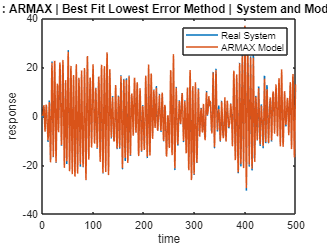

%%
figure(1)
plot(t_val,y3_val,t_val,BestFit_y_hat_3)
legend('Real System','ARMAX Model')
title(" System III : ARMAX | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

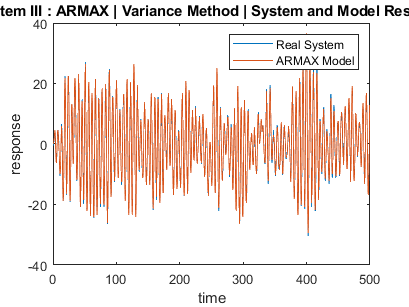


figure(2)
plot(t_val,y3_val,t_val,Var_y_hat_3)
legend('Real System','ARMAX Model')
title(" System III : ARMAX | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

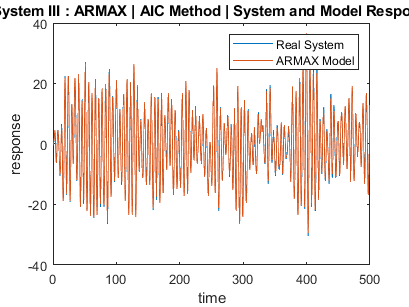


figure(3)
plot(t_val,y3_val,t_val,AIC_y_hat_3)
legend('Real System','ARMAX Model')
title(" System III : ARMAX | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

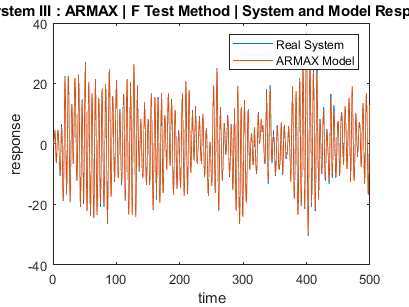


figure(4)
plot(t_val,y3_val,t_val,FTest_y_hat_3)
legend('Real System','ARMAX Model')
title(" System III : ARMAX | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

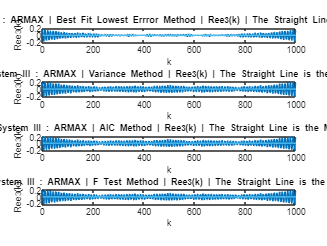

%%

figure(5)
subplot(4,1,1)
plot(1:N_val-1,armax_BestFit_Ree_3(2:end), 1:N_val-1, mean(armax_BestFit_Ree_3(2:end))*ones(length(1:N_val-1)))
title(" System III : ARMAX | Best Fit Lowest Errror Method | Ree_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_3(k)")

subplot(4,1,2)
plot(1:N_val-1,armax_Var_Ree_3(2:end), 1:N_val-1, mean(armax_Var_Ree_3(2:end))*ones(length(1:N_val-1)))
title(" System III : ARMAX | Variance Method | Ree_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_3(k)")

subplot(4,1,3)
plot(1:N_val-1,armax_AIC_Ree_3(2:end), 1:N_val-1, mean(armax_AIC_Ree_3(2:end))*ones(length(1:N_val-1)))
title(" System III : ARMAX | AIC Method | Ree_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_3(k)")

subplot(4,1,4)
plot(1:N_val-1,armax_FTest_Ree_3(2:end), 1:N_val-1, mean(armax_FTest_Ree_3(2:end))*ones(length(1:N_val-1)))
title(" System III : ARMAX | F Test Method | Ree_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_3(k)")

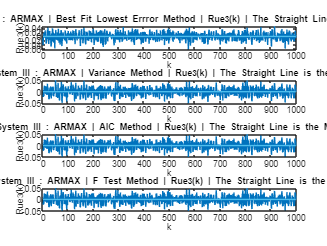

%%

figure(6)
subplot(4,1,1)
plot(1:N_val-1,armax_BestFit_Rue_3(2:end), 1:N_val-1, mean(armax_BestFit_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" System III : ARMAX | Best Fit Lowest Errror Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")

subplot(4,1,2)
plot(1:N_val-1,armax_Var_Rue_3(2:end), 1:N_val-1, mean(armax_Var_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" System III : ARMAX | Variance Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")

subplot(4,1,3)
plot(1:N_val-1,armax_AIC_Rue_3(2:end), 1:N_val-1, mean(armax_AIC_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" System III : ARMAX | AIC Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")

subplot(4,1,4)
plot(1:N_val-1,armax_FTest_Rue_3(2:end), 1:N_val-1, mean(armax_FTest_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" System III : ARMAX | F Test Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")